## Lectura de las galgas 


$$\epsilon_A=-141\mu m$$



$$\epsilon_B=180\mu m$$



$$\epsilon_C=404\mu m$$


E=200e9;
v=0.26;
G=79.3e9;
epsa=-142e-6;
epsb=180e-6;
epsc=405e-6;

#### Ángulos de la roseta

A=0;
B=45;
C=90;

### Matriz para hallar deformaciones principales


$$\left\lbrack \begin{array}{c}
\epsilon_a \\
\epsilon_b \\
\epsilon_c 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
\cos^2 \left(a\right) & {\textrm{sen}}^2 \left(a\right) & \cos \left(a\right)\textrm{sen}\left(a\right)\\
\cos^2 \left(b\right) & {\textrm{sen}}^2 \left(b\right) & \cos \left(b\right)\textrm{sen}\left(b\right)\\
\cos^2 \left(c\right) & {\textrm{sen}}^2 \left(c\right) & \cos \left(c\right)\textrm{sen}\left(c\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\epsilon_x \\
\epsilon_y \\
\gamma_{\textrm{xy}} 
\end{array}\right\rbrack$$


Matriz1=[cosd(A)^2 sind(A)^2 cosd(A)*sind(A);
         cosd(B)^2 sind(B)^2 cosd(B)*sind(B);
         cosd(C)^2 sind(C)^2 cosd(C)*sind(C);];
Vector_def=[epsa; epsb; epsc];
deformaciones_principales=inv(Matriz1)*Vector_def;
Epsilon_x=deformaciones_principales(1)

Epsilon_x = -1.4200e-04

Epsilon_y=deformaciones_principales(2)

Epsilon_y = 4.0500e-04

Gamma_xy=deformaciones_principales(3)

Gamma_xy = 9.7000e-05

### Para pasar de deformaciones principales a esfuerzos


$$\left\lbrack \begin{array}{c}
\sigma_x \\
\sigma_y 
\end{array}\right\rbrack =\frac{1}{E}\left\lbrack \begin{array}{cc}
1 & -\nu \\
-\nu  & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\epsilon_x \\
\epsilon_y 
\end{array}\right\rbrack$$


Matriz_hooke=1/E*[1 -v; -v 1];
vector1=[Epsilon_x;Epsilon_y];
vector_resultados=inv(Matriz_hooke)*vector1;
Sigma_x=vector_resultados(1)

Sigma_x = -7.8722e+06

Sigma_y=vector_resultados(2)

Sigma_y = 7.8953e+07

Tau_xy=G*Gamma_xy

Tau_xy = 7.6921e+06

## Círculo de Mohr


$$\sigma_{\textrm{prom}} =\frac{\left(\sigma_x +\sigma_y \right)}{2}$$



$$\textrm{Radio}=\sqrt{{\left(\sigma_x -\sigma_{\textrm{prom}} \right)}^2 +\tau_{\textrm{xy}}^2 }$$



$$\begin{array}{l}
\textrm{P1}=\sigma_{\textrm{prom}} +\textrm{Radio}\\
\textrm{P2}=\sigma_{\textrm{prom}} -\textrm{Radio}\\
\tau_{\max } =\textrm{Radio}
\end{array}$$


Sigma_prom=(Sigma_x+Sigma_y)/2;
Radio=sqrt((Sigma_x-Sigma_prom)^2+(Tau_xy)^2);
P1=Sigma_prom+Radio

P1 = 7.9629e+07

P2=Sigma_prom-Radio

P2 = -8.5484e+06

Tau_max=Radio

Tau_max = 4.4089e+07

### Gráfica

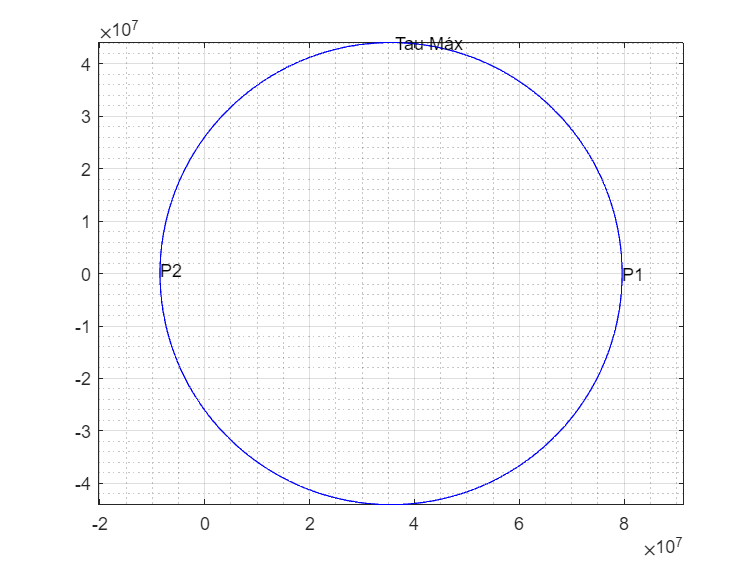

for i = 0:360
    x(i+1) = Sigma_prom + cosd(i) * Radio;
    y(i+1) = sind(i) * Radio;
end

figure(1)
plot(x, y, 'b')
grid on 
grid minor
axis equal
text(x(90),y(90),'Tau Máx')
text(x(1),y(1),'P1')
text(x(180),y(180),'P2')

## Círculo de Mohr para deformaciones 


$$\epsilon_y=-141\mu m$$



$$\epsilon_{OB}=180\mu m$$



$$\epsilon_x=404\mu m$$



$$\epsilon_{\textrm{prom}} =\frac{\epsilon_x +\epsilon_y }{2}$$



$$R=\sqrt{{\left(\frac{\epsilon_x -\epsilon_y }{2}\right)}^2 +{\left(\frac{\gamma_{\textrm{xy}} }{2}\right)}^2 }$$



$$\gamma_{\textrm{xy}} =2\epsilon_{\textrm{OB}} -\left(\epsilon_x +\epsilon_y \right)$$



$$E_1 =\epsilon_{\textrm{prom}} +R$$



$$E_2 =\epsilon_{\textrm{prom}} -R$$


epsx=-142e-6;
epsy=405e-6;
eob=180e-6;
gamma_xy=2*eob-(epsx+epsy)

gamma_xy = 9.7000e-05

eps_prom=(epsx+epsy)/2

eps_prom = 1.3150e-04

Rdef=sqrt(((epsx-epsy)/2)^2+(gamma_xy)^2);
gamma_max=Rdef

gamma_max = 2.9019e-04

E1=eps_prom+Rdef

E1 = 4.2169e-04

E2=eps_prom-Rdef

E2 = -1.5869e-04